% Function to calculate the surface heat transfer coefficient, assuming
% that an empirical equation of the form {Nu=a Re^n * Pr^m * Gr^q} is available to
% approximate the local rheological and thermophysical properties of the
% fluid film in contact with the solid surface

function h=ForcedConvecCoeff(rho_air,mu_m,k_m,cp_m,V,Lc,a_h,m_h,n_h,q_h,ambtemp,Ts)


Computing the Reynolds Number

where:

ρ          Density of the moist air (kg/m3)

 of the solid

V            Fluid velocity (m/s)

$\mu$             dynamic viscosity of the moist air (kg/m.s)

Re=rho_air*Lc*V/mu_m;

Computing the Prandtl Number (which is dependent only on the fluid and the fluid state)

where:

 of the moist air

$\alpha$            Thermal diffusivity of the moist air

k               thermal conductivity of the moist air (W/m C)

Pr=cp_m*mu_m/k_m;

Computing the Grashof Number 

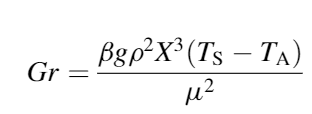

where:

 is the volumetric expansion coefficient for any gas at constant temperature, and  is the absolute air temperature in Kelvin

g is gravitational acceleration

X is a length dimension

beta=1/(ambtemp+273.15);
Gr=beta*9.81*rho_air^2*Lc^3*abs(Ts-ambtemp)/mu_m^2;

Computing the Nusselt Number

Nu=a_h*Re.^n_h*Pr.^m_h*Gr.^q_h;

Solving the defining equation of the Nusselt Number to get h, the convection coefficient:

h=Nu*k_m/Lc;
end